## **Creating the Learning Factory Environment**

## **Creating the Learning Factory Environment**

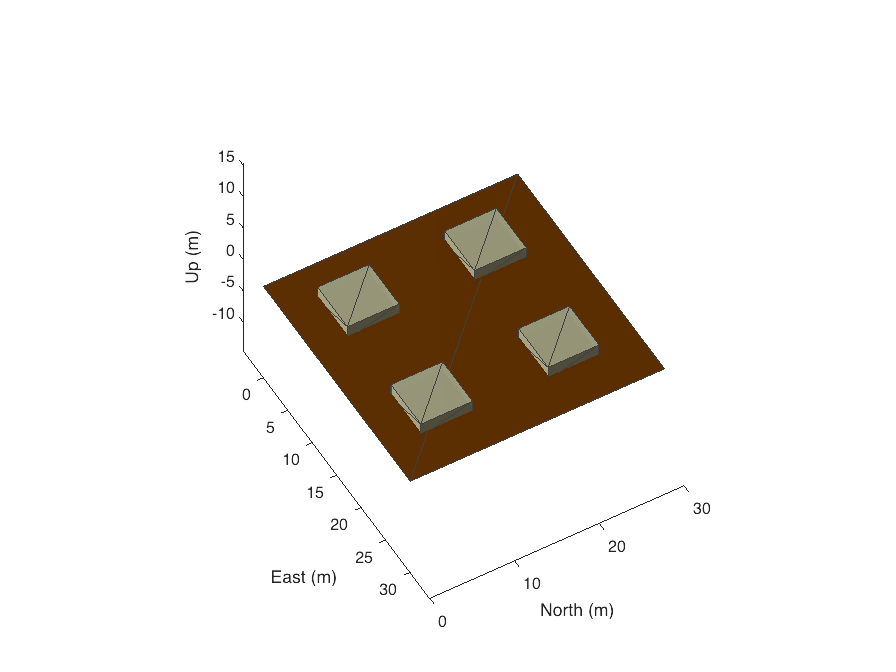

envc = EnvironmentConstants();
[obstacles, robotScenario, gridSize] = envc.createRobotScenerioEnvironment2();
show3D(robotScenario);
lightangle(-45,30);
view(60,50);

## Load the agent and create the simulink things

contents = load("experiments_comparison_points/experiment_2_points.mat", "points");
importantCoordinates = contents.points;

## Creating the variables for statistics

numTrials = 100;

numFailures = zeros(numTrials,3);
runTimes = zeros(numTrials,1);
numDeadlocks = zeros(numTrials,1);
numCollisions = zeros(numTrials,1);

distancesTravelled = zeros(numTrials,2);
safetyScores = zeros(numTrials,2);
smoothnessScores = zeros(numTrials,2);

## Create the tasks

rng(0) 
for trial=1:numTrials
    %step 1
    rng(trial)
    selected_indices = randperm(length(importantCoordinates),6);
    locations = importantCoordinates(selected_indices,:);
    %format the input string

    stringInput = embedJSON([locations(1,:); locations(4,:)],[locations(2,:); locations(5,:)], [locations(3,:); locations(6,:)],[locations(1,:); locations(4,:)], [1; 2]);
    tic
    taskControlAgent = TaskControlAgent(gridSize, obstacles);
    reservedRoutes = taskControlAgent.executeControl(stringInput, taskControlAgent.PRIORITISED);
    toc

    taskControlAgent.tasks.startCoordinates

    runTimes(trial) = toc;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ANALYSE THE ROUTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [maxElements, longestIdx] = max(cellfun(@numel, reservedRoutes));
    numRows = maxElements/2;
    [minElements, shortestIdx] = min(cellfun(@numel, reservedRoutes));
    
    waypoints = {};
    for rIndex=1:length(reservedRoutes)
        thisRoute = reservedRoutes{rIndex};
        currentLength = size(thisRoute,1);
        if currentLength < numRows
            %if the current route is shorter than the longest one then repeat
            %the end to the right length
            temp = zeros(numRows-currentLength,2);
            temp = temp+thisRoute(end,:);
            reservedRoutes{rIndex} = [thisRoute; temp];
        end
        %adjust the coordinates correctly
        temp = zeros(length(reservedRoutes{rIndex}), 2);
        for rIndex2=1:numRows
            currentCoords = reservedRoutes{rIndex}(rIndex2,:);
            temp(rIndex2,:) = [currentCoords(1)-0.5, currentCoords(2)-0.5]; 
        end
        waypoints{rIndex} = temp;
    end
    route1 = waypoints{1};
    route2 = waypoints{2};
    
    %Calculate the Distance Travelled
    travelDistance1 = distanceTravelled(route1);
    travelDistance2 = distanceTravelled(route2);

    %Calculate the Number of Collisions
    totalLength = size(reservedRoutes{longestIdx},1);
    collisions = 0;
    for lIndex=1:totalLength 
        amr1loc = route1(lIndex,:);
        amr2loc = route2(lIndex,:);
    
        locations = [amr1loc; amr2loc];
        collisions = collisions + checkCollisions(locations);
    end

    %Calculate the Number of Deadlocks
    routes = {route1, route2};
    deadlocks = checkDeadlocks(route1, route2);
    
    
    disp("check")
    numFailures(trial, :)
    deadlocks
    collisions
    disp("__________")

    failures = [0 0 0];
    numFailures(trial,:) = failures;
    numDeadlocks(trial) = deadlocks;
    numCollisions(trial) = collisions;
    
    distancesTravelled(trial,:) = [travelDistance1 travelDistance2];
    smoothnessScores(trial,:) = calculateSmoothnessScores({route1, route2});
    safetyScores(trial,:) = calculateSafetyScores({route1, route2});

    %if trial == 12 
    %    [obstacles, robotScenario, gridSize] = envc.createRobotScenerioEnvironment2();
    %    tasks = taskControlAgent.getTasks();
    %    robots = taskControlAgent.getMobileRobots();
    %    temp = simulateExperiment(waypoints, importantCoordinates, tasks, robots, robotScenario)
    %end
    %if collisions > 0 || deadlocks > 0 
    %    [obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
    %    travelDistances = simulateExperiment(waypoints, tasks, robots, scenario);
    %end
end

Elapsed time is 2.982187 seconds.


ans =     29     5


ans =     23     1


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.422144 seconds.


ans =      1    16


ans =      8    17


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.175448 seconds.


ans =     28     2


ans =      1    16


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.920344 seconds.


ans =     11    30


ans =     29     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.306229 seconds.


ans =     29     5


ans =     23     1


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.255264 seconds.


ans =     17    15


ans =     15    25


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.936568 seconds.


ans =     17    15


ans =     11    30


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.549905 seconds.


ans =     17    15


ans =     28     2


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.944185 seconds.


ans =      1    16


ans =      8    17


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.232411 seconds.


ans =     29     5


ans =      9    19


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.150679 seconds.


ans =      9    19


ans =      5     4


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.098413 seconds.


ans =      1    28


ans =     17    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.429690 seconds.


ans =     11    30


ans =      5     4


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.760699 seconds.


ans =      5     4


ans =     17    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.579398 seconds.


ans =     11    30


ans =     29    26


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.087737 seconds.


ans =      8    17


ans =     17    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.299906 seconds.


ans =     17    15


ans =      9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.964470 seconds.


ans = 1×2
     1    28


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.851357 seconds.


ans = 1×2
     8    17


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.311504 seconds.


ans = 1×2
     9    19


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.155791 seconds.


ans = 1×2
     8    17


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.065906 seconds.


ans = 1×2
    28     2


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.516829 seconds.


ans = 1×2
    29    26


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.951384 seconds.


ans = 1×2
    15    25


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.314815 seconds.


ans = 1×2
    23     1


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.054714 seconds.


ans = 1×2
    17    15


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.476208 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.302127 seconds.


ans = 1×2
    29    26


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.973839 seconds.


ans = 1×2
     9    19


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.496732 seconds.


ans = 1×2
    17    15


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.549771 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.202791 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.384422 seconds.


ans = 1×2
     8    17


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.167872 seconds.


ans = 1×2
     9    19


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.409682 seconds.


ans = 1×2
     1    16


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.250024 seconds.


ans = 1×2
    23     1


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.534389 seconds.


ans = 1×2
     9    19


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.668410 seconds.


ans = 1×2
    17    15


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.306117 seconds.


ans = 1×2
    17    15


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.273935 seconds.


ans = 1×2
     8    17


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.841371 seconds.


ans = 1×2
    15    25


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.353562 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.609203 seconds.


ans = 1×2
     8    17


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.308999 seconds.


ans = 1×2
     1    16


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.503226 seconds.


ans = 1×2
     1    16


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.401268 seconds.


ans = 1×2
    29    26


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.881547 seconds.


ans = 1×2
     5     4


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.975731 seconds.


ans = 1×2
     5     4


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.899389 seconds.


ans = 1×2
     1    16


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.287348 seconds.


ans = 1×2
    23     1


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.159292 seconds.


ans = 1×2
    23     1


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.153959 seconds.


ans = 1×2
     9    19


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.180668 seconds.


ans = 1×2
    15    25


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.097884 seconds.


ans = 1×2
     1    28


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.978794 seconds.


ans = 1×2
     8    17


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.114200 seconds.


ans = 1×2
    15    25


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.554540 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.999822 seconds.


ans = 1×2
    29    26


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.839861 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.587453 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.384817 seconds.


ans = 1×2
    15    25


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.874550 seconds.


ans = 1×2
     8    17


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.847062 seconds.


ans = 1×2
    17    15


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.516123 seconds.


ans = 1×2
    17    15


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.800889 seconds.


ans = 1×2
    17    15


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.333424 seconds.


ans = 1×2
     1    28


ans = 1×2
    23     1


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.245336 seconds.


ans = 1×2
     9    19


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.043858 seconds.


ans = 1×2
     8    17


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.030551 seconds.


ans = 1×2
     1    28


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.099273 seconds.


ans = 1×2
    15    25


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.893369 seconds.


ans = 1×2
    15    25


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.024332 seconds.


ans = 1×2
    29     5


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.987579 seconds.


ans = 1×2
    23     1


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.736320 seconds.


ans = 1×2
     8    17


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.455266 seconds.


ans = 1×2
     1    16


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.752410 seconds.


ans = 1×2
     8    17


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.246671 seconds.


ans = 1×2
    29     5


ans = 1×2
    15    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.629398 seconds.


ans = 1×2
    17    15


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.484278 seconds.


ans = 1×2
     5     4


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.493030 seconds.


ans = 1×2
    17    15


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.243957 seconds.


ans = 1×2
     9    19


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.171115 seconds.


ans = 1×2
    28     2


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.058658 seconds.


ans = 1×2
    17    15


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.959219 seconds.


ans = 1×2
    23     1


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.809909 seconds.


ans = 1×2
    11    30


ans = 1×2
    29     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.014194 seconds.


ans = 1×2
    29    26


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.225156 seconds.


ans = 1×2
     1    28


ans = 1×2
     1    16


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.250838 seconds.


ans = 1×2
    29     5


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.100980 seconds.


ans = 1×2
     9    19


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.716487 seconds.


ans = 1×2
    29    26


ans = 1×2
     8    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.296674 seconds.


ans = 1×2
     8    17


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.080784 seconds.


ans = 1×2
    29    26


ans = 1×2
    17    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.523211 seconds.


ans = 1×2
     9    19


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.175549 seconds.


ans = 1×2
    11    30


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.484510 seconds.


ans = 1×2
    17    15


ans = 1×2
     5     4


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.743209 seconds.


ans = 1×2
     5     4


ans = 1×2
    29    26


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.246004 seconds.


ans = 1×2
    11    30


ans = 1×2
    28     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.949541 seconds.


ans = 1×2
    29    26


ans = 1×2
     9    19


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.312188 seconds.


ans = 1×2
     1    16


ans = 1×2
    11    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.321264 seconds.


ans = 1×2
    11    30


ans = 1×2
     1    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________



%Run Times
runTimes

runTimes = 100×1
    3.0149
    3.4299
    3.1814
    2.9262
    3.3169
    3.2863
    1.9424
    2.5574
    2.9501
    3.2685


numFailures

numFailures = 100×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


numDeadlocks

numDeadlocks = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


numCollisions

numCollisions = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distancesTravelled

distancesTravelled = 100×2
    50    98
    86    96
    72    98
    72    82
    80    98
    72    78
    64    46
    56    92
   104    66
   104    54


smoothnessScores

smoothnessScores = 100×2
    4.7124   12.5664
   10.9956   10.9956
   10.9956    6.2832
   12.5664   17.2788
   14.1372   14.1372
   12.5664   10.9956
    9.4248    7.8540
    9.4248   10.9956
    6.2832   15.7080
   12.5664   12.5664


safetyScores

safetyScores = 100×2
     0     0
     4     4
     0     0
     1     1
     4     4
     3     3
     0     0
     0     0
     1     1
     0     0



save('experiments_comparison_results/experiment_2_new_prioritised_ga.mat','runTimes','numFailures','numDeadlocks','numCollisions','distancesTravelled','smoothnessScores','safetyScores');
